## Analysis Pipeline for PEP WP-4 EEG Project

### House keeping

clc; clear; close all;%dbstop if error;
cfg = struct;
d = struct;

% add functions folder to path
cfg.functionPath = fullfile(pwd,'utilities');
addpath(genpath(cfg.functionPath))

### Define to-be-analyzed subjects

cfg.subNums = [101:106, 109:113, 115:117, 119:122, 124, 126:127, 130, 140]; % 118 did not finish the experiment
cfg = defaultCfg(cfg);

### Preprocessing

disp(['Running pre-processing...' newline]);

Running pre-processing...



preprocess_EEG(cfg);

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

### Category decoding

disp(['Running decoding...' newline]);

Running decoding...



% decoding_EEG(cfg);

### Individual decoding accuracies

disp(['Running individual decoding...' newline]);

Running individual decoding...



% individual_decoding_accuracies(cfg);

### Pairwise decoding

cfg.plotting = true;
disp(['Running pairwise decoding...' newline]);

Running pairwise decoding...



RDM for sub-101 already exists
RDM for sub-102 already exists
RDM for sub-103 already exists
RDM for sub-104 already exists
RDM for sub-105 already exists
RDM for sub-106 already exists
RDM for sub-109 already exists
RDM for sub-110 already exists
RDM for sub-111 already exists
RDM for sub-112 already exists
RDM for sub-113 already exists
RDM for sub-115 already exists
RDM for sub-116 already exists
RDM for sub-117 already exists
RDM for sub-119 already exists
RDM for sub-120 already exists
RDM for sub-121 already exists
RDM for sub-122 already exists
RDM for sub-124 already exists
RDM for sub-126 already exists
RDM for sub-127 already exists
RDM for sub-130 already exists
RDM for sub-140 already exists


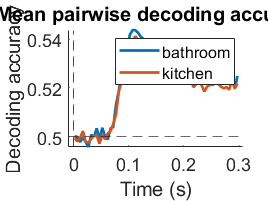

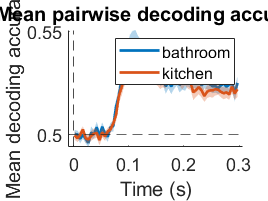

[d.pairRep, cfg] = PairwiseTPLDAclassifier(cfg);

### ISC of representation

cfg.plotting = true;
cfg.regressOutMean = false;
disp(['Running ISC...' newline]);

Running ISC...



Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dimensions
Length of labels do not match matrix dim

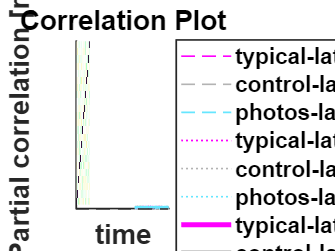

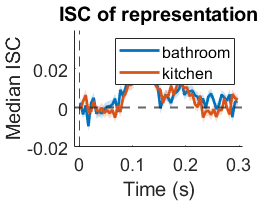

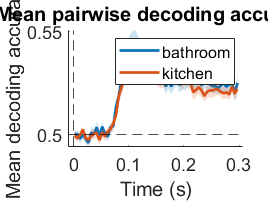

d = getISCofRespresentation(cfg, d);

### ISC of representation with regressOutMean

cfg.regressOutMean = true;
cfg.dissimilarity = true;
cfg.ISC_types = {'pairRep'};
cfg.correlation_type = 'spearman';
cfg.plotting = true;
cfg.new_figure = false;
disp(['Running ISC...' newline]);

Running ISC...



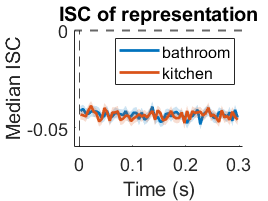

d = getISCofRespresentation(cfg, d);

### **t-test**

cfg.plotting = true;
disp(['Running t-test on pairwise decoding accuracies...' newline]);
stats_ttest(cfg, d);

### Get inter-subject similarity on drawings

cfg.dnn = 'vgg16_imagenet';
cfg.layer_type = 'late';
cfg.correlation_type = 'Spearman';
cfg.dissimilarity = true;
cfg.plot_rdm = true;

% Create output directory if wanted
output_dir = fullfile(pwd, '..', 'dnn_features');
if exist(output_dir, 'dir')
    rmdir(output_dir, 's');
end

% get images
cfg.analysis_names = {'typical', 'control','photos'};
images = load_images(cfg);

Loaded image: 101_bat_gen1.png
Loaded image: 101_bat_gen2.png
Loaded image: 101_bat_gen3.png
Loaded image: 102_bat_gen1.png
Loaded image: 102_bat_gen2.png
Loaded image: 102_bat_gen3.png
Loaded image: 103_bat_gen1.png
Loaded image: 103_bat_gen2.png
Loaded image: 103_bat_gen3.png
Loaded image: 104_bat_gen1.png
Loaded image: 104_bat_gen2.png
Loaded image: 104_bat_gen3.png
Loaded image: 105_bat_gen1.png
Loaded image: 105_bat_gen2.png
Loaded image: 105_bat_gen3.png
Loaded image: 106_bat_gen1.png
Loaded image: 106_bat_gen2.png
Loaded image: 106_bat_gen3.png
Loaded image: 107_bat_gen1.png
Loaded image: 107_bat_gen2.png
Loaded image: 107_bat_gen3.png
Loaded image: 108_bat_gen1.png
Loaded image: 108_bat_gen2.png
Loaded image: 108_bat_gen3.png
Loaded image: 109_bat_gen1.png
Loaded image: 109_bat_gen2.png
Loaded image: 109_bat_gen3.png
Loaded image: 110_bat_gen1.png
Loaded image: 110_bat_gen2.png
Loaded image: 110_bat_gen3.png
Loaded image: 111_bat_gen1.png
Loaded image: 111_bat_gen2.png
Loaded i

analysis typical - layer #1 - category: bathroom
Length of labels do not match matrix dimensions


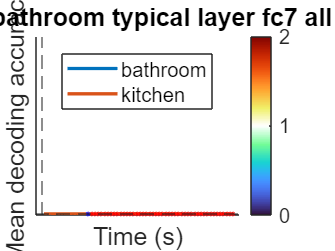

analysis control - layer #1 - category: bathroom
Length of labels do not match matrix dimensions


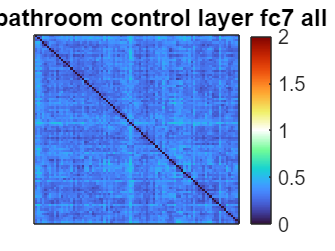

analysis photos - layer #1 - category: bathroom
Length of labels do not match matrix dimensions


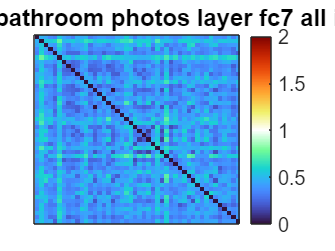

analysis typical - layer #1 - category: kitchen
Length of labels do not match matrix dimensions


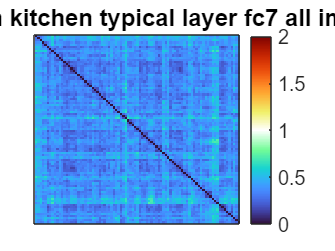

analysis control - layer #1 - category: kitchen
Length of labels do not match matrix dimensions


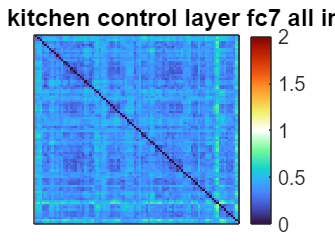

analysis photos - layer #1 - category: kitchen
Length of labels do not match matrix dimensions


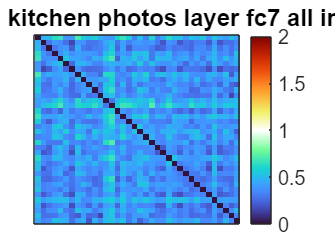

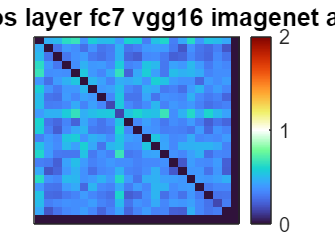


% layer similiarity
[d, cfg] = get_dnn_layer_similarity(d, images, cfg); % in the function cfg.regressOutMean = false!


% filter for included subjects
d = filterCurrentSubs(d, cfg);


### Compare ISC from drawings with ISC of neural representations 

 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated


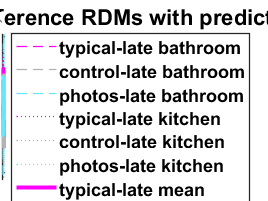

% preparation
cfg.partial_cor = true;
cfg.plotting = true;
cfg.predictor_RDMs = {'typical_late', 'control_late', 'photos_late'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
cfg.dnns = {'vgg16_imagenet'};
cfg.show_single_cate = true;
cfg.partial_correlation_type = 'pearson';

% run
d = compare_tp_RDMs_to_predictor_RDMs(d, cfg);

End Message

% finished!
disp([ ...
    newline, ...
    '#########################', ...
    newline, ...
    '####### ALL DONE! #######', ...
    newline, ...
    '#########################', ...
    newline ...
    ]);


#########################
####### ALL DONE! #######
#########################

